## **Data Import**

df_out = readmatrix("rateandpdata5000.csv");
df = readmatrix("newtestcase.csv");

## Input features

poro = df(:,2);
perm = df(:,1)* 1000; %darcies to mD
rate_coef = df(:,4);
rho = df(:,5)* 0.0624279606; %kg/m3 to lb/ft3
mu = df(:,6); %cp
pwf_prod_bc = df(:,3)* 0.0689475728; %bars to psia


## Functional Links

p1 = pwf_prod_bc ./ rate_coef;
p2 = poro .* perm;
p3 = mu ./ perm;
p4 = rate_coef ./ perm;
p5 = log(pwf_prod_bc).*log(perm);
p6 = pwf_prod_bc ./ rho;
p7 = rho .* mu;
p8 = rate_coef ./ poro;

## Target values

pwf_inj = df_out(:,1:36) * 0.00014503773800722;
qW_prod = abs(df_out(:,109:144) * 543439); %% Rate unit is m3/day, convert to bbl/day
qO_prod = abs(df_out(:,181:216) * 543439);
dt = (1:36)*10;
% qW_inj = df_out(:,73:108) * 6.29; %No need to include
% qO_inj = df_out(:,145:180) * 6.29; % No need to include


x = ([poro perm rho mu pwf_prod_bc p2 p3 p4 p5])';
y1 = ([pwf_inj])';
y2 = qW_prod' ;
y3 = qO_prod';
y = [y1; y2; y3];

## **Data Visualization**

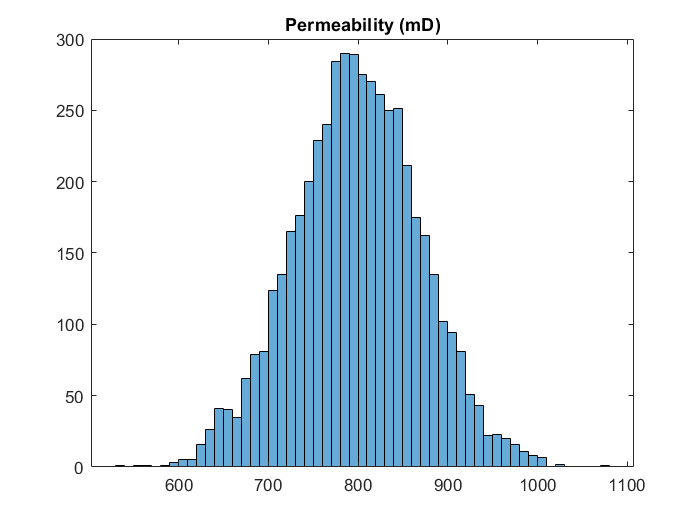

figure;
histogram(perm)
title('Permeability (mD)');

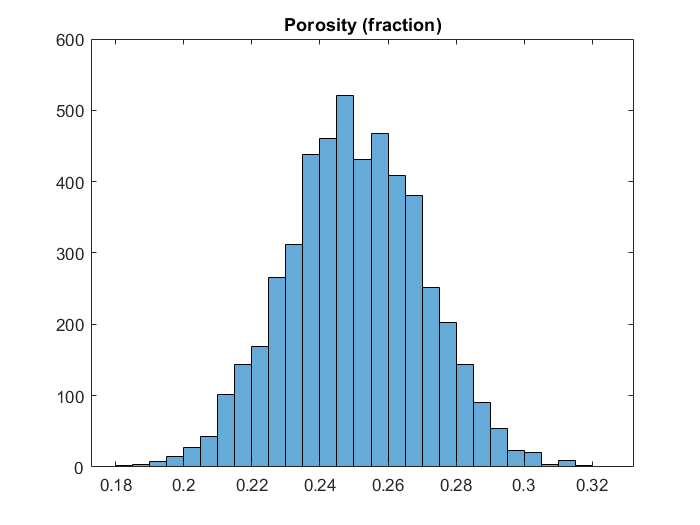

figure;
histogram(poro)
title("Porosity (fraction)")

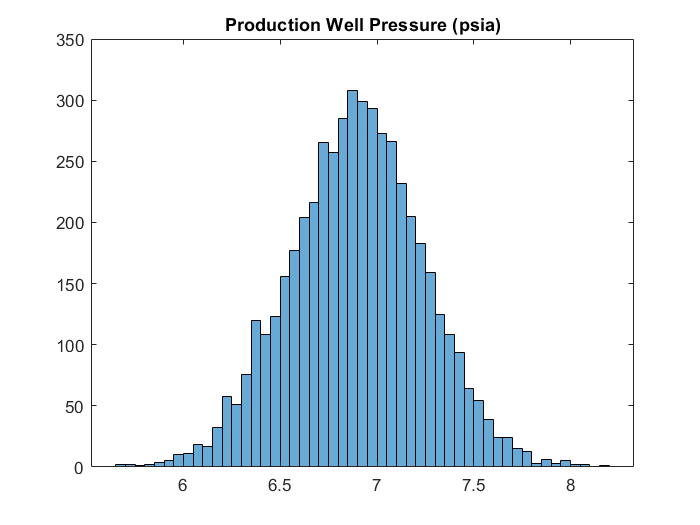

figure;
histogram(pwf_prod_bc)
title("Production Well Pressure (psia)")

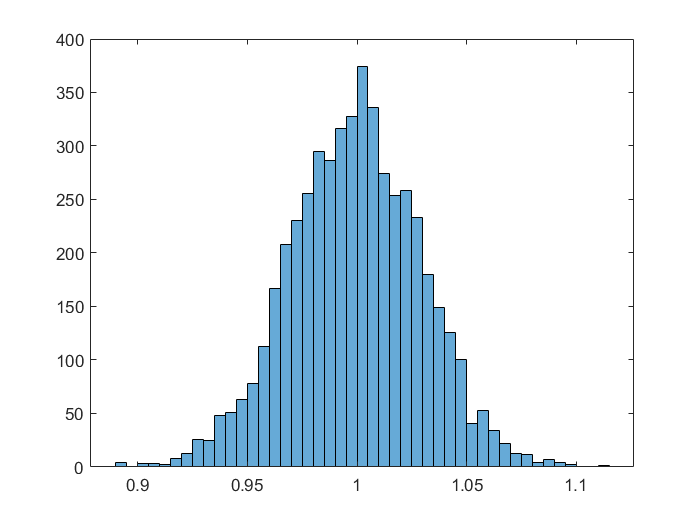

figure;
title("Rate Coefficient")
histogram(rate_coef)

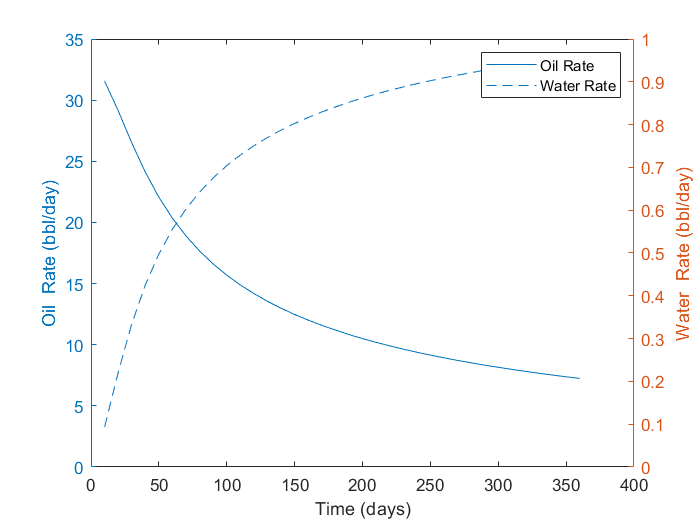

figure;
yyaxis left
plot(dt,qO_prod(length(qO_prod),:));
xlabel('Time (days)')
ylabel('Oil  Rate (bbl/day)')
hold on
plot(dt,qW_prod(1,:));
yyaxis right
ylabel('Water  Rate (bbl/day)')
legend('Oil Rate','Water Rate')
hold off

## Searching for the Best Shallow ANN Size

% sizes = 10:10:200;
%  for i = 1: length(sizes)
%     layersize = sizes(i);
%     net = fitnet(sizes(i),'trainscg'); net.trainParam.max_fail = 8;
%     net.trainParam.epochs = 5000; net.divideParam.trainRatio = 0.7;
%     net.divideParam.valRatio = 0.15; net.divideParam.testRatio = 0.15;
%     [net, tr] = train(net,x,y,'useGPU','yes'); 
%     yTrain_true =y(:,tr.trainInd); 
%     yTrain_estimates =sim(net,x(:,tr.trainInd),'useGPU','yes');
%     yVal_true =   y(:,tr.valInd); 
%     yVal_estimates =sim(net,x(:,tr.valInd),'useGPU','yes'); 
%     mse_train(i) =mean(((yTrain_estimates-yTrain_true).^2),'all'); 
%     mse_val(i) =mean(((yVal_estimates-yVal_true).^2),'all');
%  end
% figure;
% plot(sizes,mse_train);
% hold on;
% plot(sizes,mse_val);
% xlabel("Size of the Layer")
% ylabel("Average Cost")
% legend('Training','Validation');

## Chosen Shallow ANN Size and Visual Fits

chosen_net_size = 40; 
alphanet = fitnet(chosen_net_size,'trainscg');
alphanet.trainParam.max_fail = 10; alphanet.trainParam.epochs = 10000;
alphanet.divideParam.trainRatio = 0.7; alphanet.divideParam.valRatio = 0.15; alphanet.divideParam.testRatio = 0.15;
[alphanet, trprop] = train(alphanet,x,y);
yTrain_chosen = y(:,trprop.trainInd);
yVal_chosen = y(:,trprop.valInd);
yTest_chosen = y(:,trprop.testInd);
yTrain_chosenEst =sim(alphanet,x(:,trprop.trainInd)); 
yVal_chosenEst =sim(alphanet,x(:,trprop.valInd)); 
yTest_chosenEst =sim(alphanet,x(:,trprop.testInd)); 
mse_train_chosen =mean(((yTrain_chosenEst-yTrain_chosen).^2),'all'); 
mse_val_chosen =mean(((yVal_chosenEst-yVal_chosen).^2),'all');
mse_test_chosen =mean(((yTest_chosenEst-yTest_chosen).^2),'all');
fprintf('Average costs for each set is: %2f, %2f,%2f ',mse_train_chosen,mse_val_chosen,mse_test_chosen)

Average costs for each set is: 0.474547, 0.353639,0.535781 

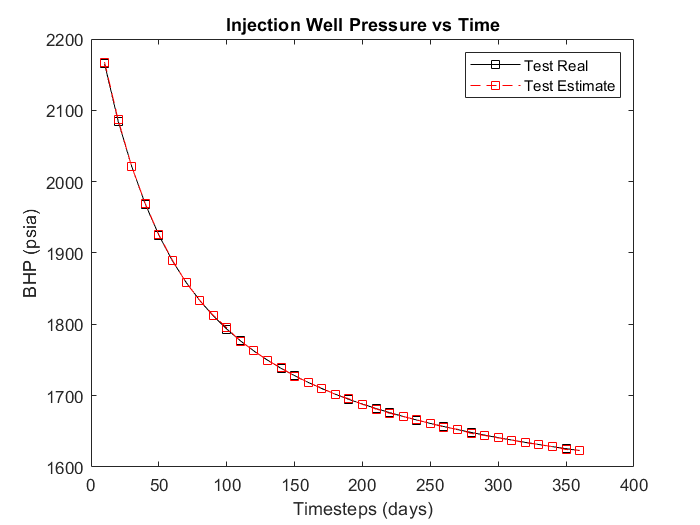

figure;
plot(dt,yTest_chosen(1:36,1),'k','Marker',"square")
hold on
plot(dt,yTest_chosenEst(1:36,1),'r--','Marker',"square")
xlabel("Timesteps (days)")
ylabel("BHP (psia)")
title("Injection Well Pressure vs Time")
legend("Test Real","Test Estimate")

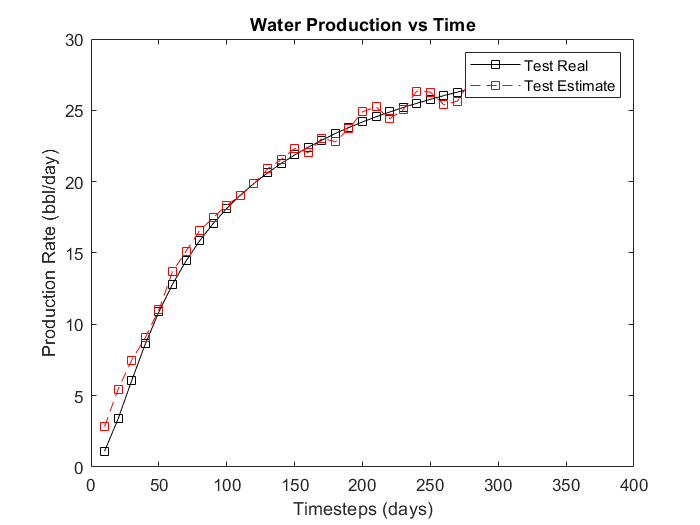


figure;
plot(dt,yTest_chosen(37:72,1),'k','Marker',"square")
hold on
plot(dt,yTest_chosenEst(37:72,1),'r--','Marker',"square")
xlabel("Timesteps (days)")
ylabel("Production Rate (bbl/day)")
title("Water Production vs Time")
legend("Test Real","Test Estimate")

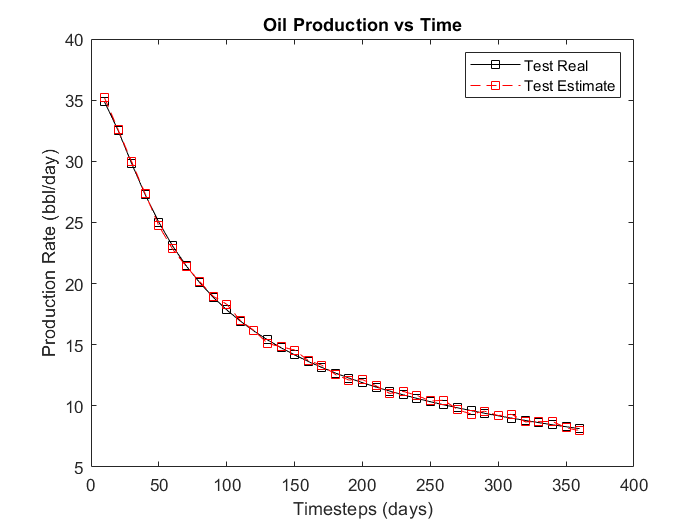


figure;
plot(dt,yTest_chosen(73:108,2),'k','Marker',"square")
hold on
plot(dt,yTest_chosenEst(73:108,2),'r--','Marker',"square")
xlabel("Timesteps (days)")
ylabel("Production Rate (bbl/day)")
title("Oil Production vs Time")
legend("Test Real","Test Estimate")

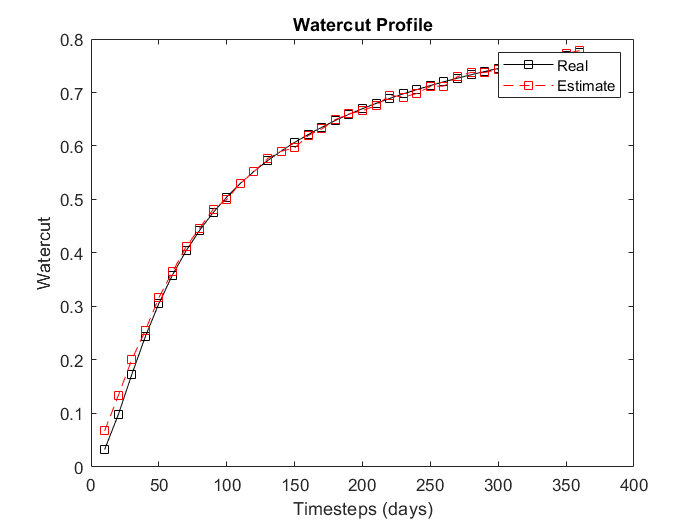


figure;
plot(dt,yTest_chosen(37:72,2)./(yTest_chosen(37:72,2)+yTest_chosen(73:108,2)),'k','Marker',"square")
hold on
plot(dt,yTest_chosenEst(37:72,2)./(yTest_chosenEst(37:72,2)+yTest_chosenEst(73:108,2)),'r--','Marker',"square")
title("Watercut Profile")
xlabel("Timesteps (days)")
ylabel("Watercut")
legend('Real','Estimate')

## Multilayer Perceptron Model

%     net = fitnet([50 40],'trainscg'); net.trainParam.max_fail = 10;
%     net.trainParam.epochs = 8000; net.divideParam.trainRatio = 0.7;
%     net.divideParam.valRatio = 0.15; net.divideParam.testRatio = 0.15;
%     [net, tr] = train(net,x,y,'useGPU','yes'); 
%     yTrain_true =y(:,tr.trainInd); 
%     yTrain_estimates =sim(net,x(:,tr.trainInd),'useGPU','yes');
%     yVal_true =   y(:,tr.valInd); 
%     yVal_estimates =sim(net,x(:,tr.valInd),'useGPU','yes'); 
%     mse_train_deep =mean(((yTrain_estimates-yTrain_true).^2),'all'); 
%     mse_val_deep =mean(((yVal_estimates-yVal_true).^2),'all');

% figure;
% plot(deepsizes,mse_train);
% hold on;
% plot(deepsizes,mse_val);
% xlabel("Size of the Layer")
% ylabel("Average Cost")
% legend('Training','Validation');